## Stillbilder

clear
image = double(imread('baboon.png'))

image =    150    57    43    94   140    97    51    25    70    66    91   157   155   111    74   152   195   127    77   102    75    92   113    72    77   126   126    65    61   168   179    65    72   148   154    96    75    70   183    75    26    75   179   171    71   126   111   136   151   118
   125    97    35    72    86    52    61    48   103    58    63    90   114    39    37   121   152   132   130    34    44    49    66    58   138   184   187   110    49    88   182   165    76   107   195   128   139    70   126   107    29    45    91   171   195   119   145    90   152   171
    74   118    41    46   106    58    58    45   122   117    48    63    70    35    18    48   129   111    91    56    76    50    36    63    99   189   212   181    95    41    98   180   166    84   132   120   109   109   120   141    84   149   141   130   149   161   151   153    88   132
    79   144    98    51    89   127    49    46    73    97    55    49    47    24    2

%image = double(imread('boat.png'));
%image = double(imread('woodgrain.png'));

[x,y] = size(image);



p = distribution2d(image);
H1 = entropyOfDistribution(p)

H1 = 7.4745

#### Parentropi horisontellt


$$H\left(X_{i,j} ,X_{i+1,j} \right)$$



data = reshape(image,1,x*y);

horizontal_data = zeros(size(data));

horizontal_data(1,1) = data(1,1);
% Skiftar
for i = 2:size(data,2)
%     data(1,i)-data(1,i-1)
    horizontal_data(1,i) = data(1,i) - data(1,i-1);
end

horizontal_data

horizontal_data =    150   -25   -51     5     5     0   -46   -15    31   -22    -5     1     4   -13    -3    54    13   -30     5    58    39   -74   -38     7    36    34   -18    33   -20   -78    48   -38    15    18     2   -21     9   -22    -2    50   -37   -19    11    22     8    10   -27    68   -77   -10


min(horizontal_data)

ans = -198


% Tar bort negativa värden
horizontal_data = minshift(horizontal_data);

p2 = distribution(horizontal_data')

p2 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


H_hori = entropyOfDistribution(p2)

H_hori = 6.8975

#### Parentropi vertikalt


$$H\left(X_{i,j} ,X_{i,j+1} \right)$$


% Transponera bilden ger vertikala grannar
data = reshape(image',1,x*y);
vertical_data = zeros(size(data));

vertical_data(1,1) = data(1,1);
% Skiftar
for i = 2:size(data,2)
    vertical_data(1,i) = data(1,i) - data(1,i-1);
end
% Tar bort negativa värden
vertical_data = minshift(vertical_data);

p3 = distribution(vertical_data');
H_vert = entropyOfDistribution(p3)

H_vert = 6.5521

#### Betingad


$$\left.H\left(X_{i+1,j} \right|X_{i,j} \right)$$


H_hori_cond = H_hori - H1

H_hori_cond = -0.5769

 H(Xi,j+1 | Xi,j) 

H_vert_cond = H_vert - H1

H_vert_cond = -0.9223

#### Huffmankodning


$$Y_{i,j} =X_{i,j} -P_{i,j}$$



l2 = huffman(p2)

l2 = 6.9323

l3 = huffman(p3)

l3 = 6.5818


data = padarray(image,[1 1],128, 'both');

pe1 = image;
%Horizontal
for x = 2:size(image,1) 
    for y = 2:size(image,2) 
        %newimage(x,y) = data(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
        pe1(x,y) = pe1(x,y) - data(x-1,y);
    end
end

%Vertical
pe2 = image;
for x = 2:size(image,1) 
    for y = 2:size(image,2) 
        %newimage(x,y) = data(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
        pe2(x,y) = pe2(x,y) - data(x,y-1);
    end
end

%Conditional
pe3 = image;
for x = 2:size(image,1) 
    for y = 2:size(image,2) 
        %newimage(x,y) = data(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
        pe3(x,y) = pe3(x,y) - (data(x-1,y) + data(x,y-1) - data(x-1,y-1));
    end
end

l = huffman(p)

l = 7.5171

H1 = entropyOfDistribution(p)

H1 = 7.4745


%prediction_error = prediction_error(2:end-1,2:end-1);
%prediction_error = minshift(prediction_error);
[row,col] = size(pe1);
data_l4_h = reshape(pe1,row*col,1);
data_l4_h = minshift(data_l4_h)

data_l4_h =    350
   325
   274
   279
   284
   284
   238
   223
   254
   232


p4_h = distribution(data_l4_h);
l4_h = huffman(p4_h)

l4_h = 7.2685

H_hori = entropyOfDistribution(p4_h)

H_hori = 7.2411


[row,col] = size(pe2);
data_l4_v = reshape(pe2,row*col,1);
data_l4_v = minshift(data_l4_v)

data_l4_v =    359
   334
   283
   288
   293
   293
   247
   232
   263
   241


p4_v = distribution(data_l4_v);
l4_v = huffman(p4_v)

l4_v = 7.2355

H_vert = entropyOfDistribution(p4_v)

H_vert = 7.2104


[row,col] = size(pe3);
data_l4_c = reshape(pe3,row*col,1);
data_l4_c = minshift(data_l4_c)

data_l4_c =    398
   373
   322
   327
   332
   332
   286
   271
   302
   280


p4_c = distribution(data_l4_c);
l4_c = huffman(p4_c)

l4_c = 7.3819

H_cond = entropyOfDistribution(p4_c)

H_cond = 7.3582

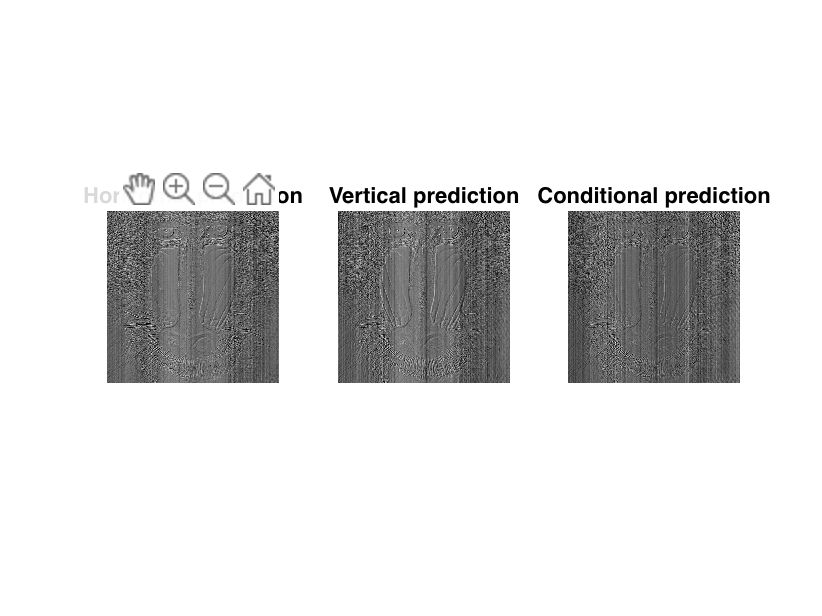



figure;
subplot(1,3,1);
imshow(minshift(pe1) / max(max(minshift(pe1))))
txt1 = ['Bitrate: ' num2str(l4_h)];
title('Horizontal prediction');
subtitle(txt1)

subplot(1,3,2);
imshow(minshift(pe2) / max(max(minshift(pe2))))
title('Vertical prediction');
txt2 = ['Bitrate: ' num2str(l4_v)];
subtitle(txt2)

subplot(1,3,3);
imshow(minshift(pe3) / max(max(minshift(pe3))))
title('Conditional prediction');
txt3 = ['Bitrate: ' num2str(l4_c)];
subtitle(txt3)